% A0 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\Probe\eta5\BT-E-+50mV-+-5Vg.csv");
% A1 = readmatrix("C:\Users\mgorbun\Documents\Vilnus\2025-11-13_eta5\I-V_dF_IV_b.dat");
A2 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\TDS\setup-test\2025-0220-empty-LE.csv");
% A3 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\TDS\setup-test\2025-0220-Si-NE.csv");
% A4 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\TDS\aper22122025\SLOW X_40.50_Y_33.50_13_03_04_34.csv");
% A5 = readmatrix("C:\Users\mgorbun\Documents\MATLAB\TDS\gatedgr\2025-0130_3mm_g-0i.csv");
disp(1)

% A0 = movmean(A0, 30);
% A1 = movmean(A1, 30);
A2 = movmean(A2, 100);
% A3 = movmean(A3, 10);
% A4 = movmean(A4, 10);

A0(:,2) = A1(:,2) ./ A3(:,2);

y = A0(:,2);
idx = find(diff(sign(diff(y))) < 0) + 1;   % кандидаты максимумов
thr = 0.8*max(y);                          
idx = idx(y(idx) > thr);  

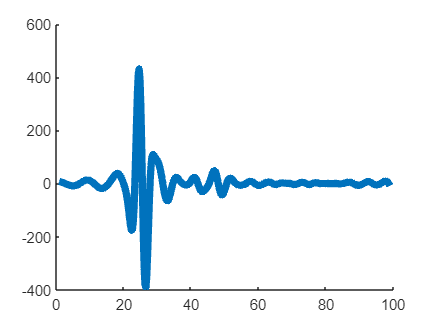

lw = 1;
figure
hold on
% plot(A0(:,1), A0(:,2), "LineWidth", lw, "DisplayName", "0")
% plot(A1(:,3), A1(:,4), "LineWidth", lw, "DisplayName", "1")
plot(A2(1:20:end,1), A2(1:20:end,2), "LineWidth", 5, "DisplayName", "2")

% plot(A3(:,1), A3(:,2), 'b-', "LineWidth", lw, "DisplayName", "3")
% plot(A4(:,1), A4(:,2), 'r-', "LineWidth", lw, "DisplayName", "4")
% plot(A5(:,1), A5(:,2), 'b-', "LineWidth", lw, "DisplayName", "5")
% scatter(A0(idx,1), A0(idx,2))
% legend
